clc
clear
close all
rng('default');

set(0, 'defaultAxesFontSize', 12)
set(0, 'DefaultLineLineWidth', 2);
set(0, 'defaultAxesFontSize', 14)
set(0, 'defaultAxesTickLabelInterpreter','latex');
set(0, 'defaultlegendInterpreter','latex')

## Data generation

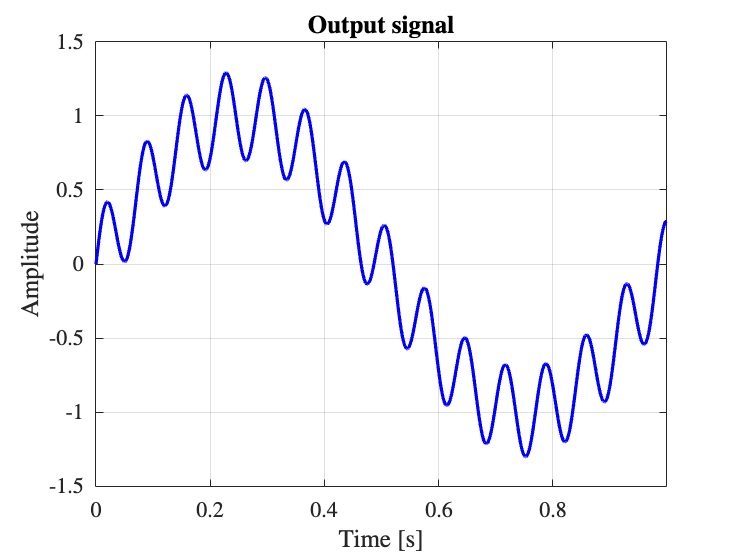

Ts = 1e-3; % sampling time
fs = 1/Ts; % sampling frequency
N = 1000; % number of measured data. For N = k*T1, we have no leakeage on T1
T = N*Ts; % observation window length [s]
bin = 1 / T; % frequency bin [Hz]
time = (0:Ts:T-Ts)'; % observation time [s]
freqs = [0 bin:bin:(N/2-1)*bin]; % grid of discrete frequencies


T1 = 1; T2 = 0.07; % period of the signal components [s]
f1 = 1/T1; f2 = 1/T2;  % frequency of the signal components [Hz]
a1 = 1; a2 = 0.3; % amplitudes of the frequency components
y = a1 * sin(2*pi*f1.*time) + a2 * sin(2*pi*f2.*time); % generate signal with frequencies not integer multiples of the bin, so leakeage is present


figure
plot(time , y, 'b'); grid on;
xlabel('Time [s]', 'interpreter', 'latex');
ylabel('Amplitude', 'interpreter', 'latex');
title('\textbf{Output signal}', 'interpreter', 'latex');
xlim([0, time(end)]);

## Estimate spectrum

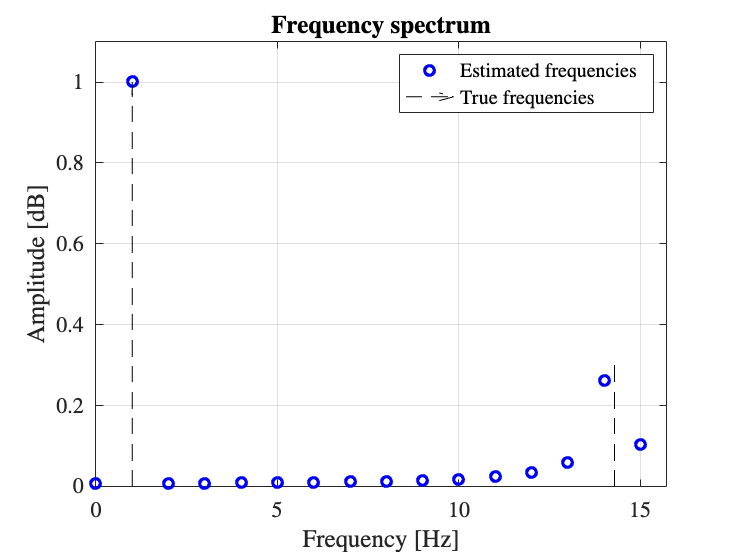

% spectrum of measured data
spectrum = abs( fft(y)/N );
spectrum = 2 * spectrum(1:floor(N/2));


figure
plot(freqs, (spectrum), 'bo', 'markersize' , 6); hold on;
p1 = [f1 0]; p2 = [f1 (a1)]; dp = p2 - p1;
quiver(p1(1),p1(2),dp(1),dp(2),0, 'k--', 'MaxHeadSize',0.1, 'LineWidth', 0.5)
p1 = [f2 0]; p2 = [f2 (a2)]; dp = p2 - p1;
quiver(p1(1),p1(2),dp(1),dp(2),0, 'k--', 'MaxHeadSize',0.1, 'LineWidth', 0.5)
xlim([0, 1.1*max([f1, f2])]); ylim([0, 1.1*max([a1, a2])]);
grid on; legend('Estimated frequencies', 'True frequencies', 'interpreter', 'latex');
xlabel('Frequency [Hz]', 'interpreter', 'latex');
ylabel('Amplitude [dB]', 'interpreter', 'latex');
title('\textbf{Frequency spectrum}', 'interpreter', 'latex');